clc; clear; close all;

step = 0.01;
time_of_motion = 3;
time_of_hold = 1;
time_total = 3*(time_of_hold + time_of_motion)+1;
t = 0:step:time_total;

arrange = [1,2,2,3,3,1,2,1,3]';
num_panels = length(arrange);
M = repmat(arrange,1,length(t));

Signals = zeros(size(M));
offset1 = 0;
offset2 = 0;
offset3 = 1;
for i = 1:num_panels
    if arrange(i) == 2
        Signals(i,offset1+((time_of_motion+time_of_hold)/step):end-1/step) = 1;
        offset1 = offset1 + 10;
    elseif arrange(i) == 3
        Signals(i,offset2+(2*time_of_motion+2*time_of_hold)/step:end-1/step) = 1;
        offset2 = offset2 + 10;
    elseif arrange(i) == 1
        Signals(i,offset3:end-1/step) = 1;
        offset3 = offset3 + 10;
    end   
end

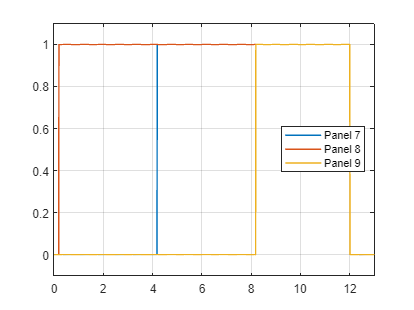

plot(t,Signals(:,:),'LineWidth',1.2)
legends = cell(num_panels,1);
for i = 1:num_panels
    legends{i} = append('Panel ', int2str(i));
end
legend(legends,'Location','east')
ylim([-0.1,1.1])
xlim([0,13])
grid on